i = 1

i = 2

i = 3

i = 5

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

part =

Time domain data set with 88 samples.   
Sample time: 1 days                      
                                         
Outputs               Unit (if specified)
   Behavior                              
                                         
Inputs                Unit (if specified)
   Goals                                 
   Expected Points                       
   Granted Points                        
   PredBusy                              
   PredStress                            
   PredTypical                           
   Wknd                                  
   Temperature                           
                                         


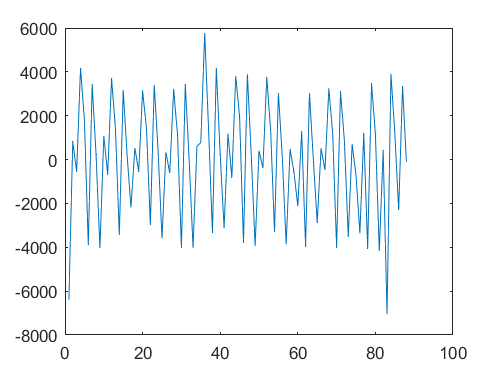

% Control Systems Engineering Lab 2022 - DSPSA applied to ARX models for
% Behavioral Intervention

% NOTE: Use with Just Walk Participant Access and Save to JW-SPSA-ssved


clear all;clc;


msg = "Choose Output Signal";
opts = ["Goal Attainment" "Behavior" "Goal Achievement"];
choice_out= menu(msg,opts);

if choice_out==1
    database_ga
elseif choice_out==2
    load meta.mat
    meta_cpy=meta
elseif choice_out==3
    database_gachieve
end



% interact = 0 to only use single terms, set interact >= 1 (i.e. 1, 2, 3,...) for one
% or more interaction terms
interact = 0;

% To only use interaction terms interactonly = 1; to use both interaction
% terms and regular inputs interactonly == 0 (for only regular inputs,
% interactonly == 0 & interact == 0).
interactonly = 0;


if interactonly == 1 & interact == 0
    error('No terms specified - check interact and interactonly.')
end

if interactonly == 1
    run JW_participant_access_cycles %To obtain participant data and interaction terms only
    indx_inp = indx_int; %For later on
else
    run JW_participant_access_cycles %To obtain participant data
end

numind = num2str(indx_inp);
indx_names = numind(~isspace(numind));

% Sampling time
T  = 1;  % 1 sec I think

a = size(overall);
ny = a(1,2); %Number of outputs
nu = a(1,3); %Number of inputs


%%%%%%%%%%%%%%%%%
%% USER INPUTS %%
%%%%%%%%%%%%%%%%%
tic
Niterations = 20; 
spsaw = 1; % spsaw = 1 for feature selection, spsaw = 0 for no feature selection

% Objective function Weights -- change as needed.
estw = 0;
valw = 0.6;
ovew = 0.4;
weights = [estw valw ovew]; %To save all weights

% Specify feature selection parameters
    [urow ucol] = size(overall2.u); %To create binary vector, w, of length of inputs 
    w = 0.5*ones(ucol,1); % Initialize input vector -- Change coefficient as needed.
    ck = 0.1; % keep small for perturbation size 
    afs = 0.003; % a > 0
    Afs = 0.1*Niterations; % A >= 0
    alphafs = 0.501; % 0.5 < alpha <= 1
    %ak = 0.0002; % keep small for small step iterations (from approximated gradient)
    % ak is specified in for loop (k)
    gainfs = [afs Afs alphafs ck]; %Save ak and ck values 

% Specify parameters for ARX order alloptimization
    carx = 1; % In Wang&Spall 2014, they only use ak for DSPSA --> I set carx = 1 for no impact on calculations
    aarx = 0.1; % a > 0 Stick with 0.1 -0 0.3
    Aarx = 0.1*Niterations; % A >= 0 ; Recommended in Qi Wang 2013 (dissertation)
    alphaarx = 0.501; % 0.5 < alpha <= 1 ; Recommended in Qi Wang 2013 (dissertation)
    gainarx = [aarx Aarx alphaarx carx]; % Save ak and ck for arx 

    arxstructure = [2 2 1]; % Initialize ARX values Change structure as needed
    
    na = arxstructure(1,1)*ones(ny,ny); % Initialize ARX values
    nb = arxstructure(1,2)*ones(ny,nu);
    nk = arxstructure(1,3)*ones(ny,nu);
    
% Specify constant ARX orders
    % To keep constant, set nXconst = 1, specify constant value in NX for
    % X in {a,b,k}. These constant values are the same for all inputs and outputs
    naconst = 0; 
        NA = 0; %NA is the constant value of na for naconst == 1
        
    nbconst = 0;
        NB = 1; %NB is the constant value of nb for nbconst == 1 
        
    nkconst = 0;
        NK = 0; %NK is the constant value of nk for nkconst == 1

% Specify ARX Order BOUNDS
    naub = 3; % na upper and lower bound
    nalb = 1;

    nbub = 3; % nb upper and lower bound
    nblb = 1;

    nkub = 1; % nk upper and lower bound
    nklb = 0;


tic; % Start Timer to Track Execution Time
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Start of SPSA for cycles %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

setdata = cycledata; % Sets up structure (from cycledata)
estvaldata = JWestvaldata; % Sets up structure (from JWestvaldata)
setarx = JWarx; % Sets up structure (from JWarx)

% Estimation and Validation Data Cycles for comparison -- binarized
evset = [
    1 1 0 0 0
    1 0 1 0 0 
    1 0 0 1 0 
    1 0 0 0 1
    0 1 1 0 0 
    0 1 0 1 0
    0 1 0 0 1
    0 0 1 1 0
    0 0 1 0 1
    0 0 0 1 1
    0 0 1 1 1
    0 1 0 1 1
    0 1 1 0 1
    0 1 1 1 0
    1 0 0 1 1
    1 0 1 0 1
    1 0 1 1 0 
    1 1 0 0 1 
    1 1 0 1 0
    1 1 1 0 0]; % From Freigoun, et. al 2017 (ACC paper)

     iodata1 = getexp(overall,1); 
     iodata2 = getexp(overall,2);
     iodata3 = getexp(overall,3);
     iodata4 = getexp(overall,4);
     iodata5 = getexp(overall,5);
     
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% START FOR LOOP TO EVALUATE EST/VAL CYCLES  (q loop) %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for q = 1:1:length(evset) % Change to 1:1:length(evset)

    eset = find(evset(q,:) == 1);
    valset = find(evset(q,:) == 0);
    
    overallest = getexp(overall,eset); 
    overallval = getexp(overall,valset);

    iodata = overallest; % Estimation cycles
    iodatav = overallval; % Validation cycles

    iodata_all = overall2; % overall2 is all of the data, NOT segemented into cycles
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
%%%%%% BEGIN SPSA ITERATIONS %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   

for k = 1:1:Niterations
    ak = afs/(k+Afs+1)^alphafs;  % ak for FEATURES From Wang & Spall 2014  
    akarx = aarx/(k+Aarx+1)^alphaarx;  % ak for REGRESSOR ORDERS From Wang & Spall 2014  
    c = ck; % From Aksakalli & Malekipirbazari 2016 (ck = c, constant value)
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % INITIALIZE FEATURE SELECTION %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if spsaw == 1 % If using SPSA for feature selection
        % New values of w
        wint = floor(w) + 0.5 % As per Step 3 of Wang & Spall 2014
        
        wplus = zeros(ucol,1); % Initialize wplus and wminus -- updated with delta later
        wminus = zeros(ucol,1);
        z = zeros(ucol,1); % To prevent all of wplus or wminus from being all zeros
        
        %while isequal(round(wplus),z) || isequal(round(wminus),z) % TO PREVENT ALL ZEROS 
            for i = 1:1:length(w)
                delta(i,1) = 2*round(rand(1))-1; %random perturbation for each input
                
                %To create two points to estimate the gradient
                wplus(i,1) = wint(i,1) + ck*delta(i,1); 
                wminus(i,1) = wint(i,1) - ck*delta(i,1);
            end 

            if (isequal(round(wplus),z) || isequal(round(wminus),z)) == 1 % TO PREVENT ALL ZEROS 
                delta(i,1) = 2*round(rand(1))-1; %random perturbation for each input
                
                %To create two points to estimate the gradient
                wplus(i,1) = wint(i,1) + ck*delta(i,1); 
                wminus(i,1) = wint(i,1) - ck*delta(i,1);
                else 
            end
        %end

        % Set bounds on wplus and wminus (binary)
        for i = 1:1:length(wplus)
            if wplus(i,1) >1 %if greater than 1, make it 1
                wplus(i,1) = 1;
            end
            
            if wplus(i,1) < 0 %if less than 0 make it 0
                wplus(i,1) = 0;
            end
        end
        for i = 1:1:length(wminus)
            if wminus(i,1) >1 %if greater than 1, make it 1
                wminus(i,1) = 1;
            end
            
            if wminus(i,1) < 0 %if less than 0 make it 0
                wminus(i,1) = 0;
            end
        end

    else % If SPSA NOT used for feature selection
        w = ones(ucol,1);
        wplus = w;
        wminus = w;
        %delta = ones(ucol,1);
    end
%    wplus
%    wminus
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% INITIALIZE REGRESSOR ORDERS %%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Create ARX+ and ARX-
    [a, b] = size(overall2.u);
        
     arxzerosplus = find((round(wplus)' == 0));
     arxzerosminus = find((round(wminus)' == 0));
           
    %%%%%%%%%%%%
    %%%% NA %%%% 
    %%%%%%%%%%%%
        if naconst == 1
            naplus = NA.*ones(size(na));
            naminus = NA.*ones(size(na));

        else
            napm = floor(na) + 0.5; %recommended from Step 3 of Wang & Spall 2014
            for i = 1:1:ny
                deltana(1,i) = 2*round(rand(1))-1; %random perturbation for each input
                
                naplus(1,i) = napm(1,i) + carx*deltana(1,i);
                    if naplus(1,i) < nalb %Bound ARX orders
                        naplus(1,i) = nalb;
                    end
                    if naplus(1,i) > naub
                        naplus(1,i) = naub;
                    end
                
                naminus(1,i) = napm(1,i) - carx*deltana(1,i);
                    if naminus(1,i) < nalb %Bound ARX orders
                        naminus(1,i) = nalb;
                    end
                    if naminus(1,i) > naub %Bound ARX orders
                        naminus(1,i) = naub;
                    end
            end
        end

    %%%%%%%%%%%%
    %%%% NB %%%% 
    %%%%%%%%%%%%

        if nbconst == 1
            nbplus = NB.*ones(size(nb));
            nbminus = NB.*ones(size(nb));
        else
            nbpm = floor(nb) + 0.5;
            for i = 1:1:b %*** ASSUMES NY = 1 *****
                deltanb(1,i) = 2*round(rand(1))-1; %random perturbation for each input
                deltank(1,i) = 2*round(rand(1))-1; %random perturbation for each input
                
                %To create two points to estimate the gradient -- nb
                nbplus(1,i) = nbpm(1,i) + carx*deltanb(1,i); 
                    if nbplus(1,i) < nblb %Bound ARX orders
                        nbplus(1,i) = nblb;
                    end        
                    if nbplus(1,i) > nbub %Bound ARX orders
                        nbplus(1,i) = nbub;
                    end   
                    
                nbminus(1,i) = nbpm(1,i) - carx*deltanb(1,i);
                    if nbminus(1,i) < nblb %Bound ARX orders
                        nbminus(1,i) = nblb;
                    end
                    if nbminus(1,i) > nbub %Bound ARX orders
                        nbminus(1,i) = nbub;
                    end
            end
        end

    %%%%%%%%%%%%
    %%%% NK %%%% 
    %%%%%%%%%%%%

        if nkconst == 1
            %nkplus = NK.*ones(size(nkplus));
            %nkminus = NK.*ones(size(nkminus));
            nkplus = NK.*ones(size(nk));
            nkminus = NK.*ones(size(nk));
        else
            %To create two points to estimate the gradient -- nk
            nkpm = floor(nk) + 0.5;
            for i = 1:1:b %*** ASSUMES NY = 1 *****
                nkplus(1,i) = nkpm(1,i) + carx*deltank(1,i); 
                    if nkplus(1,i) < nklb %Bound ARX orders
                        nkplus(1,i) = nklb;
                    end
                    if nkplus(1,i) > nkub %Bound ARX orders
                        nkplus(1,i) = nkub;
                    end
                    if nkplus(1,i) == 0 && nbplus(1,i) == 0 % nb and nk cannot both be 0 for the same input
                        nkplus(1,i) = nkub; % ASSUMING nkub = 1
                    end
                              
                nkminus(1,i) = nkpm(1,i) - carx*deltank(1,i);
                    if nkminus(1,i) < nklb %Bound ARX orders
                        nkminus(1,i) = nklb;
                    end   
                    if nkminus(1,i) > nkub %Bound ARX orders
                        nkminus(1,i) = nkub;
                    end 
                    if nbminus(1,i) == 0 && nkminus(1,i) ==0 % nk and nb cannot both be 0 for the same input
                        nkminus(1,i) = nkub; % ASSUMING nkub = 1
                    end
             end
        end

        
        nbplus(:,arxzerosplus) = []; % Resize nbplus and nbminus
        nbminus(:,arxzerosminus) = [];
        
        nkplus(:,arxzerosplus) = []; % Resize nkplus and nkminus
        nkminus(:,arxzerosminus) = [];
        
    %Redefine iodata and iodatav for two fit evaluations (for gradient
    %approximation) -- remove columns corresponding to outputs; keep inputs
    %only
    stu = ny + 1; %start of input columns (start u --> stu)
    
    %% REDEFINE ESTIMATION DATA (IODATA) %%
    % PLUS
    wplus_inp = find(round(wplus) == 1);
    iodataplus = iodata(:,outputchannels,inputchannels(wplus_inp)); %[iodata(:,1:ny) inputiodata.*round(wplus')];
        [nyplus,nuplus] = size(wplus_inp);
        narxsplus = round([naplus.*ones(ny,ny) nbplus.*ones(ny,nuplus) nkplus.*ones(ny,nuplus)]);
            stplus = 1;
       
    
    % MINUS
    wminus_inp = find(round(wminus) == 1);
    iodataminus = iodata(:,outputchannels,inputchannels(wminus_inp)); %[iodata(:,1:ny) inputiodata.*round(wminus')];
        [nyminus,numinus] = size(wminus_inp);
        narxsminus = round([naminus.*ones(ny,ny) nbminus.*ones(ny,numinus) nkminus.*ones(ny,numinus)]);
            stminus = 1;

            
    %% REDEFINE VALIDATION DATA (IODATAV) %%
    iodata1plus = [iodata1.y iodata1.u(:,wplus_inp')];%[cyc1plus.y cyc1plus.u];
    iodata2plus = [iodata2.y iodata2.u(:,wplus_inp')];%[cyc2plus.y cyc2plus.u];
    iodata3plus = [iodata3.y iodata3.u(:,wplus_inp')];%[cyc3plus.y cyc3plus.u];
    iodata4plus = [iodata4.y iodata4.u(:,wplus_inp')];%[cyc4plus.y cyc4plus.u];
    iodata5plus = [iodata5.y iodata5.u(:,wplus_inp')];%[cyc5plus.y cyc5plus.u];

    iodata_allplus = [overall2.y overall2.u(:,wplus_inp')]; % All Data

    iodata1minus = [iodata1.y iodata1.u(:,wminus_inp)];%[cyc1minus.y cyc1minus.u];
    iodata2minus = [iodata2.y iodata2.u(:,wminus_inp)];%[cyc2minus.y cyc2minus.u];
    iodata3minus = [iodata3.y iodata3.u(:,wminus_inp)];%[cyc3minus.y cyc3minus.u];
    iodata4minus = [iodata4.y iodata4.u(:,wminus_inp)];%[cyc4minus.y cyc4minus.u];
    iodata5minus = [iodata5.y iodata5.u(:,wminus_inp)];%[cyc5minus.y cyc5minus.u];

    iodata_allminus = [overall2.y overall2.u(:,wminus_inp)]; % All Data
    
    % Mean subtracted %
    % Validation Data
    
    for it1 = 1:1:ny % Don't need this for loop, because ny=1
        arxmodelplus=arx(iodataplus,narxsplus);  
        arxmodelminus=arx(iodataminus,narxsminus);
        
        % Evaluate Plus
        [arx_result_1plus percent_arx_1plus]=compare(iodata1plus,arxmodelplus); % On Cycle 1
        [arx_result_2plus percent_arx_2plus]=compare(iodata2plus,arxmodelplus); % On Cycle 2
        [arx_result_3plus percent_arx_3plus]=compare(iodata3plus,arxmodelplus); % On Cycle 3
        [arx_result_4plus percent_arx_4plus]=compare(iodata4plus,arxmodelplus); % On Cycle 4
        [arx_result_5plus percent_arx_5plus]=compare(iodata5plus,arxmodelplus); % On Cycle 5

        [arx_result_plus percent_arx_plus] = compare(iodata_allplus,arxmodelplus); % On overall data

        cyclefitplus(k,1) = (1-(norm(iodata1plus(stplus:end,it1)-arx_result_1plus(stplus:end,it1)))/(norm(iodata1plus(stplus:end,it1) - mean(iodata1plus(stplus:end,it1)) )))*100;
        cyclefitplus(k,2) = (1-(norm(iodata2plus(stplus:end,it1)-arx_result_2plus(stplus:end,it1)))/(norm(iodata2plus(stplus:end,it1) - mean(iodata2plus(stplus:end,it1)) )))*100; %percent_arx_2plus;
        cyclefitplus(k,3) = (1-(norm(iodata3plus(stplus:end,it1)-arx_result_3plus(stplus:end,it1)))/(norm(iodata3plus(stplus:end,it1) - mean(iodata3plus(stplus:end,it1)) )))*100; %percent_arx_3plus;
        cyclefitplus(k,4) = (1-(norm(iodata4plus(stplus:end,it1)-arx_result_4plus(stplus:end,it1)))/(norm(iodata4plus(stplus:end,it1) - mean(iodata4plus(stplus:end,it1)) )))*100; %percent_arx_4plus;
        cyclefitplus(k,5) = (1-(norm(iodata5plus(stplus:end,it1)-arx_result_5plus(stplus:end,it1)))/(norm(iodata5plus(stplus:end,it1) - mean(iodata5plus(stplus:end,it1)) )))*100; %percent_arx_5plus;

        percent_arx_e_plus = mean(cyclefitplus(k,eset),2); % Computes mean of the NRMSE fit for est
        percent_arx_v_plus = mean(cyclefitplus(k,valset),2); % Computes mean of the NRMSE fit for val
        
        percent_arx_o_plus = (1-(norm(iodata_allplus(stplus:end,it1)-arx_result_plus(stplus:end,it1)))/(norm(iodata_allplus(stplus:end,it1)- mean(iodata_allplus(stplus:end,it1)))))*100;
        %percent_arx_o_plus = mean(cyclefitplus(k,:),2); % Computes mean of the NRMSE fit for overall
        
        % Evaluate Minus
        [arx_result_1minus percent_arx_1minus]=compare(iodata1minus,arxmodelminus); % On Cycle 1
        [arx_result_2minus percent_arx_2minus]=compare(iodata2minus,arxmodelminus); % On Cycle 2
        [arx_result_3minus percent_arx_3minus]=compare(iodata3minus,arxmodelminus); % On Cycle 3
        [arx_result_4minus percent_arx_4minus]=compare(iodata4minus,arxmodelminus); % On Cycle 4
        [arx_result_5minus percent_arx_5minus]=compare(iodata5minus,arxmodelminus); % On Cycle 5

        [arx_result_minus percent_arx_minus] = compare(iodata_allminus,arxmodelminus); % On overall data

        cyclefitminus(k,1) = (1-(norm(iodata1minus(stplus:end,it1)-arx_result_1minus(stminus:end,it1)))/(norm(iodata1minus(stminus:end,it1) - mean(iodata1minus(stminus:end,it1)))))*100;
        cyclefitminus(k,2) = (1-(norm(iodata2minus(stplus:end,it1)-arx_result_2minus(stminus:end,it1)))/(norm(iodata2minus(stminus:end,it1) - mean(iodata2minus(stminus:end,it1)))))*100; %percent_arx_2plus;
        cyclefitminus(k,3) = (1-(norm(iodata3minus(stplus:end,it1)-arx_result_3minus(stminus:end,it1)))/(norm(iodata3minus(stminus:end,it1) - mean(iodata3minus(stminus:end,it1)))))*100; %percent_arx_3plus;
        cyclefitminus(k,4) = (1-(norm(iodata4minus(stplus:end,it1)-arx_result_4minus(stminus:end,it1)))/(norm(iodata4minus(stminus:end,it1) - mean(iodata4minus(stminus:end,it1)))))*100; %percent_arx_4plus;
        cyclefitminus(k,5) = (1-(norm(iodata5minus(stplus:end,it1)-arx_result_5minus(stminus:end,it1)))/(norm(iodata5minus(stminus:end,it1) - mean(iodata5minus(stminus:end,it1)))))*100; %percent_arx_5plus;

        percent_arx_e_minus = mean(cyclefitminus(k,eset),2); % Computes mean of the NRMSE fit for est
        percent_arx_v_minus = mean(cyclefitminus(k,valset),2); % Computes mean of the NRMSE fit for val
        
        percent_arx_o_minus = (1-(norm(iodata_allminus(stplus:end,it1)-arx_result_minus(stplus:end,it1)))/(norm(iodata_allminus(stplus:end,it1) - mean(iodata_allminus(stplus:end,it1)))))*100;
        %percent_arx_o_minus = mean(cyclefitminus(k,:),2); % Computes mean of the NRMSE fit for overall 
    end
    
    % Use WEIGHTED average of all 3 percent fits
    percentfitarxplusavg = (valw*percent_arx_v_plus + estw*percent_arx_e_plus + ovew*percent_arx_o_plus); % Use estw, valw, ovew for weights
    percentfitarxminavg = (valw*percent_arx_v_minus + estw*percent_arx_e_minus  + ovew*percent_arx_o_minus);
    
    % Approximate gradient(s) 
    if spsaw == 1 % Only Update w if spsaw == 1 (feature select is used)
        gk = -1*((percentfitarxplusavg-percentfitarxminavg)/(2*ck)).*delta; %multiply by -1 at the front for minimization of loss function
         ak*gk %for tuning ak (w)
    else
        gk = 0; % If not used for feature selection -- do not update w iterations
    end
    
    gkna = -1*((percentfitarxplusavg-percentfitarxminavg)/(2*carx)).*(deltana).^(-1);
        gkna*akarx %for tuning ak (arx)
    gknb = -1*((percentfitarxplusavg-percentfitarxminavg)/(2*carx)).*(deltanb).^(-1);
    gknk = -1*((percentfitarxplusavg-percentfitarxminavg)/(2*carx)).*(deltank).^(-1);
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% UPDATE INPUT VECTORS %%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % calculate w(k+1) and na,nb,nk(k+1)
    w = w - ak*gk;
    na = na - akarx*gkna;
    nb = nb - akarx*gknb;
    nk = nk - akarx*gknk;
    
    %Set bounds on values of w between 0 and 1
    for i = 1:1:length(w)
        if w(i,1) >1 %if greater than 1, make it 1
            w(i,1) = 1;
        end
        
        if w(i,1) < 0 %if less than 0 make it 0
            w(i,1) = 0;
        end
    end
    
  % Set bounds for ARX orders
    if na < nalb
        na = nalb;
    end
    if na > naub
        na = naub;
    end
    
    for i = 1:1:length(nb)
        if nb(i) < nblb
            nb(i) = nblb;
        end
        if nb(i) > nbub
            nb(i) = nbub;
        end
    end
    
    for i = 1:1:length(nk)
        if nk(i) < nklb
            nk(i) = nklb;
        end
        if nk(i) > nkub
            nk(i) = nkub;
        end
        if round(nb(i)) == 0 && round(nk(i)) == 0 % nb and nk cannot both be 0 for the same element
            nk(i) = nkub; % ASSUMING nkub = 1
        end
    end
    
   % For constant held values of na,nb,nk        
        if naconst == 1
            na = NA.*ones(size(na));
        end
        
        if nbconst == 1
            nb = NB.*ones(size(nb));
        end
        
        if nkconst == 1
            nk = NK.*ones(size(nk));
        end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% STORE UPDATED VALUES %%% -- Note: Used to plot values
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
    allw(k,:) = w'; %Store all of the w iterations
    allna(k,:) = na; %Store all of the na iterations
    allnb(k,:) = nb; %Store all of the nb iterations 
    allnk(k,:) = nk; %Store all of the nk iterations
    
    %Calculate the actual fit percents for a given w (not from wplus or
    %wminus) and P

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% EVALUATE NEW VECTORS %%% -- Used to calculate fit% at ea. iteration
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    wfinal = round(w);
    nbw = nb; % For calculating new fit% without messing with original nb,nk vectors
    nkw = nk;
    % NOTE: Only for nb and nk, because they have to be resized
    % based on which inputs are used (see narxsw)
    
    % Redefine iodata and iodatav using set of inputs found through DSPSA
    wfinal_inp = find(wfinal == 1);
    iodataw = iodata(:,outputchannels,inputchannels(wfinal_inp));
        [row,nuw] = size(wfinal_inp);
        narxsw = round([na.*ones(ny,ny) nbw(:,wfinal_inp).*ones(ny,nuw) nkw(:,wfinal_inp).*ones(ny,nuw)]);

    iodata1w = [iodata1.y iodata1.u(:,wfinal_inp)];
    iodata2w = [iodata2.y iodata2.u(:,wfinal_inp)];
    iodata3w = [iodata3.y iodata3.u(:,wfinal_inp)];
    iodata4w = [iodata4.y iodata4.u(:,wfinal_inp)];
    iodata5w = [iodata5.y iodata5.u(:,wfinal_inp)];

    iodata_allw = [overall2.y overall2.u(:,wfinal_inp)];
        
     %figure out starting point of validation
     st = 1; it1 = 1;
                          
     arxmodelw=arx(iodataw,narxsw);   % Create ARX Model from final iodata set

        [arx_result_1 percent_arx_1]=compare(iodata1w,arxmodelw); % On Cycle 1
        [arx_result_2 percent_arx_2]=compare(iodata2w,arxmodelw); % On Cycle 2
        [arx_result_3 percent_arx_3]=compare(iodata3w,arxmodelw); % On Cycle 3
        [arx_result_4 percent_arx_4]=compare(iodata4w,arxmodelw); % On Cycle 4
        [arx_result_5 percent_arx_5]=compare(iodata5w,arxmodelw); % On Cycle 5

        [arx_result_w percent_arx_w] = compare(iodata_allw,arxmodelw); % On overall data

        cyclefit(k,1) = (1-(norm(iodata1w(st:end,it1)-arx_result_1(st:end,it1)))/(norm(iodata1w(st:end,it1) - mean(iodata1w(st:end,it1)) )))*100;
        cyclefit(k,2) = (1-(norm(iodata2w(st:end,it1)-arx_result_2(st:end,it1)))/(norm(iodata2w(st:end,it1) - mean(iodata2w(st:end,it1)) )))*100; 
        cyclefit(k,3) = (1-(norm(iodata3w(st:end,it1)-arx_result_3(st:end,it1)))/(norm(iodata3w(st:end,it1) - mean(iodata3w(st:end,it1)) )))*100; 
        cyclefit(k,4) = (1-(norm(iodata4w(st:end,it1)-arx_result_4(st:end,it1)))/(norm(iodata4w(st:end,it1) - mean(iodata4w(st:end,it1)) )))*100; 
        cyclefit(k,5) = (1-(norm(iodata5w(st:end,it1)-arx_result_5(st:end,it1)))/(norm(iodata5w(st:end,it1) - mean(iodata5w(st:end,it1)) )))*100; 

        rmsarx(k,1)=norm(arx_result_1(st:end,it1)-iodata1w(st:end,it1))./sqrt(length(iodata1w(st:end,it1)));
        rmsarx(k,2)=norm(arx_result_2(st:end,it1)-iodata2w(st:end,it1))./sqrt(length(iodata2w(st:end,it1)));
        rmsarx(k,3)=norm(arx_result_3(st:end,it1)-iodata3w(st:end,it1))./sqrt(length(iodata3w(st:end,it1)));
        rmsarx(k,4)=norm(arx_result_4(st:end,it1)-iodata4w(st:end,it1))./sqrt(length(iodata4w(st:end,it1)));
        rmsarx(k,5)=norm(arx_result_5(st:end,it1)-iodata5w(st:end,it1))./sqrt(length(iodata5w(st:end,it1)));
     
        percent_arx_e(k,:) = mean(cyclefit(k,eset),2); % Computes mean of the NRMSE fit for est
        percent_arx_v(k,:) = mean(cyclefit(k,valset),2); % Computes mean of the NRMSE fit for val
        %percent_arx_o(k,:) = mean(cyclefit(k,:),2); % Computes mean of the NRMSE fit for overall
        percent_arx_o(k,:) = (1-(norm(iodata_allw(stplus:end,it1)-arx_result_w(stplus:end,it1)))/(norm(iodata_allw(stplus:end,it1) - mean(iodata_allw(stplus:end,it1)) )))*100; % On Overall Data

        rmsarx_e(k,:) =  mean(rmsarx(k,eset),2);
        rmsarx_v(k,:) =  mean(rmsarx(k,valset),2); 
        rmsarx_o(k,:) = norm(arx_result_w(st:end,it1)-iodata_allw(st:end,it1))./sqrt(length(iodata_allw(st:end,it1))); % On Overall Data
        %rmsarx_o(k,:) = mean(rmsarx(k,:),2);
     
     % Calculated Weighted Values
     percentfitarx = (valw*percent_arx_v + estw*percent_arx_e + ovew*percent_arx_o);
     rmsarx = (valw*rmsarx_v + estw*rmsarx_e + ovew*rmsarx_o);
     
     valfit = percent_arx_v; %on validation data
     estfit = percent_arx_e; %on estimation data
     ovefit = percent_arx_o; %on overall data
     fit = percentfitarx; %Weighed avg
             
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% END OF DSPSA  (k- loop) % -- Now calculate best iteration for the set (q)
%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Find best combination of inputs and design variables from DSPSA - use for final plot
 [m, mit] = max(fit) % Obtain best, based on objective function fit%
  wbest = allw(mit,:);
  
  nabest = round(allna(mit,:)); % Get best orders
  nbbest = round(allnb(mit,:));
  nkbest = round(allnk(mit,:));
  
  % na, nb, nk for features used in model ONLY
  inputzeros = find(round(wbest)' == 0);
  %nabest = nafinal; 
  %nbbest = nbfinal; 
  %nkbest = nkfinal;
  
  nbbest(:,inputzeros') = [];
  nkbest(:,inputzeros') = [];
 
  nufinal = length(find(round(wbest)' == 1)); % Resize orders based on best features
  narxs = [nabest*ones(ny,ny) nbbest.*ones(ny,nufinal) nkbest.*ones(ny,nufinal)]; % final ARX structure
             
  %Calculate the actual fit percents for a given w (not from wplus or wminus)              
     wfinal = round(wbest);
     
     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
     %% FOR EVALUATION ON VALIDATION SET %%
     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

     wfinal_inp = find(wfinal == 1);
   
     % Redefine iodata and iodatav with SPSA results -- iodata based on est
     % cycles, iodatav based on val cycles (combined)
        iodataw = iodata(:,outputchannels,inputchannels(wfinal_inp));    
        iodatavw = iodatav(:,outputchannels,inputchannels(wfinal_inp));
        iodata_allw = [overall2.y overall2.u(:,wfinal_inp)];
    
        iodata1w = [iodata1.y iodata1.u(:,wfinal_inp)];
        iodata2w = [iodata2.y iodata2.u(:,wfinal_inp)];
        iodata3w = [iodata3.y iodata3.u(:,wfinal_inp)];
        iodata4w = [iodata4.y iodata4.u(:,wfinal_inp)];
        iodata5w = [iodata5.y iodata5.u(:,wfinal_inp)];
        
     %figure out starting point of validation
         st = 1;
         %st=max(max(narxs(:,1:(ny+nufinal))))+max(max(narxs(:,(ny+nufinal+1):end)))+2;
   
     %% RUN ARX on Validation Set %%

     arxmodelw = arx(iodataw,narxs)

        [arx_result_1 percent_arx_1]=compare(iodata1w,arxmodelw); % On Cycle 1
        [arx_result_2 percent_arx_2]=compare(iodata2w,arxmodelw); % On Cycle 2
        [arx_result_3 percent_arx_3]=compare(iodata3w,arxmodelw); % On Cycle 3
        [arx_result_4 percent_arx_4]=compare(iodata4w,arxmodelw); % On Cycle 4
        [arx_result_5 percent_arx_5]=compare(iodata5w,arxmodelw); % On Cycle 5

        [arx_result_w percent_arx_w] = compare(iodata_allw,arxmodelw); % On overall data

        cyclefitw(:,1) = (1-(norm(iodata1w(st:end,it1)-arx_result_1(st:end,it1)))/(norm(iodata1w(st:end,it1) - mean(iodata1w(st:end,it1)) )))*100;
        cyclefitw(:,2) = (1-(norm(iodata2w(st:end,it1)-arx_result_2(st:end,it1)))/(norm(iodata2w(st:end,it1) - mean(iodata2w(st:end,it1)) )))*100; 
        cyclefitw(:,3) = (1-(norm(iodata3w(st:end,it1)-arx_result_3(st:end,it1)))/(norm(iodata3w(st:end,it1) - mean(iodata3w(st:end,it1)) )))*100; 
        cyclefitw(:,4) = (1-(norm(iodata4w(st:end,it1)-arx_result_4(st:end,it1)))/(norm(iodata4w(st:end,it1) - mean(iodata4w(st:end,it1)) )))*100; 
        cyclefitw(:,5) = (1-(norm(iodata5w(st:end,it1)-arx_result_5(st:end,it1)))/(norm(iodata5w(st:end,it1) - mean(iodata5w(st:end,it1)) )))*100; 

        rmsarxw(:,1)=norm(arx_result_1(st:end,it1)-iodata1w(st:end,it1))./sqrt(length(iodata1w(st:end,it1)));
        rmsarxw(:,2)=norm(arx_result_2(st:end,it1)-iodata2w(st:end,it1))./sqrt(length(iodata2w(st:end,it1)));
        rmsarxw(:,3)=norm(arx_result_3(st:end,it1)-iodata3w(st:end,it1))./sqrt(length(iodata3w(st:end,it1)));
        rmsarxw(:,4)=norm(arx_result_4(st:end,it1)-iodata4w(st:end,it1))./sqrt(length(iodata4w(st:end,it1)));
        rmsarxw(:,5)=norm(arx_result_5(st:end,it1)-iodata5w(st:end,it1))./sqrt(length(iodata5w(st:end,it1)));
     
        percent_arx_ew(:,:) = mean(cyclefitw(:,eset),2); % Computes mean of the NRMSE fit for est -- SAVED LATER
        percent_arx_vw(:,:) = mean(cyclefitw(:,valset),2); % Computes mean of the NRMSE fit for val

        percent_arx_ow(:,:) = (1-(norm(iodata_allw(stplus:end,it1)-arx_result_w(stplus:end,it1)))/(norm(iodata_allw(stplus:end,it1) - mean(iodata_allw(stplus:end,it1)) )))*100;
        %percent_arx_ow(:,:) = mean(cyclefitw(:,:),2); % Computes mean of the NRMSE fit for overall

        rmsarx_ew =  mean(rmsarxw(:,eset),2);
        rmsarx_vw =  mean(rmsarxw(:,valset),2);
        rmsarx_ow = norm(arx_result_w(st:end,it1)-iodata_allw(st:end,it1))./sqrt(length(iodata_allw(st:end,it1))); % On Overall Data
        %rmsarx_ow = mean(rmsarxw(:,:),2);

        percentfitarx = (valw*percent_arx_vw + estw*percent_arx_ew + ovew*percent_arx_ow);
        rmsarxavg = (valw*rmsarx_vw + estw*rmsarx_ew + ovew*rmsarx_ow);

% For each set of est/val data
    
    setdata(q).w = allw;
    setdata(q).na = allna;
    setdata(q).nb = allnb;
    setdata(q).nk = allnk;
    setdata(q).fititer = fit; % Objective Function Evaluation
    setdata(q).valfit = percent_arx_v; %valfit; % FITS PER ITERATION OF DSPSA for a given est/val set -- NOT BEST FITS
    setdata(q).estfit = percent_arx_e; %estfit;
    setdata(q).ovefit = percent_arx_o; %ovefit;

    finalavgs(q,:) = [percent_arx_ew percent_arx_vw percent_arx_ow percentfitarx]; % BEST FITS for a given est/val set

    setarx(q).arxmodel = arxmodelw;
    
    estvaldata(q).iodata = iodata;%iodataw;
    estvaldata(q).iodatav = iodatav;%iodatavw;
    
    setcyc1(q,:) = arx_result_1; % ARX Result for each cycle for each set from FINAL (best) iteration of SPSA per est/val cycle
    setcyc2(q,:) = arx_result_2;
    setcyc3(q,:) = arx_result_3;
    setcyc4(q,:) = arx_result_4;
    setcyc5(q,:) = arx_result_5;

    
    setfit(q,:) = cyclefitw; %cyclefitw is for best fits for each est/val set

    setrms(q,:) = rmsarxw;

    setoverallfit(q,:) = percent_arx_ow; % Overall NRMSE Fit % per set -- Redundant? See setdata(q).ovefit
    
    setw(q,:) = wfinal; % Best features for ea. cycle combination
    
end

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.0171
   -0.0171
    0.0171
   -0.0171
    0.0171
   -0.0171
    0.0171
    0.0171


ans = 0.0569

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.2701
    0.2701
    0.2701
   -0.2701
   -0.2701
   -0.2701
    0.2701
   -0.2701


ans = 0.9003

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.0921
   -0.0921
   -0.0921
    0.0921
   -0.0921
   -0.0921
    0.0921
    0.0921


ans = 0.3070

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1779
    0.1779
   -0.1779
    0.1779
   -0.1779
    0.1779
   -0.1779
    0.1779


ans = 0.5931

wint =     1.5000
    0.5000
    0.5000
    0.5000
    1.5000
    0.5000
    0.5000
    0.5000


ans =    -0.4042
    0.4042
    0.4042
    0.4042
   -0.4042
    0.4042
   -0.4042
    0.4042


ans = 1.3473

wint =     1.5000
    0.5000
    0.5000
    0.5000
    1.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1092
   -0.1092
    0.1092
    0.1092
   -0.1092
   -0.1092
   -0.1092
    0.1092


ans = -0.3642

wint =     1.5000
    0.5000
    0.5000
    0.5000
    1.5000
    0.5000
    0.5000
    0.5000


ans =     0.0672
   -0.0672
   -0.0672
   -0.0672
    0.0672
   -0.0672
    0.0672
   -0.0672


ans = 0.2241

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.0805
    0.0805
   -0.0805
   -0.0805
    0.0805
   -0.0805
   -0.0805
   -0.0805


ans = -0.2684

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1346
    0.1346
    0.1346
    0.1346
    0.1346
   -0.1346
    0.1346
   -0.1346


ans = -0.4487

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1318
   -0.1318
   -0.1318
    0.1318
    0.1318
   -0.1318
   -0.1318
    0.1318


ans = 0.4392

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =     0.1459
    0.1459
   -0.1459
    0.1459
   -0.1459
   -0.1459
    0.1459
    0.1459


ans = -0.4862

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1921
    0.1921
   -0.1921
   -0.1921
    0.1921
   -0.1921
    0.1921
    0.1921


ans = 0.6403

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    1.5000
    0.5000
    0.5000


ans =     0.1748
   -0.1748
    0.1748
   -0.1748
   -0.1748
    0.1748
    0.1748
    0.1748


ans = -0.5826

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.2331
    0.2331
    0.2331
    0.2331
    0.2331
    0.2331
   -0.2331
   -0.2331


ans = 0.7771

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.0568
    0.0568
   -0.0568
   -0.0568
    0.0568
   -0.0568
   -0.0568
    0.0568


ans = -0.1893

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1408
   -0.1408
    0.1408
   -0.1408
    0.1408
    0.1408
    0.1408
   -0.1408


ans = -0.4694

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.1079
   -0.1079
    0.1079
   -0.1079
    0.1079
    0.1079
    0.1079
    0.1079


ans = 0.3595

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =    -0.4986
    0.4986
    0.4986
    0.4986
    0.4986
   -0.4986
    0.4986
   -0.4986


ans = 1.6620

wint =     1.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =     0.2462
    0.2462
    0.2462
   -0.2462
    0.2462
    0.2462
    0.2462
    0.2462


ans = 0.8205

wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


ans =     0.0956
    0.0956
    0.0956
   -0.0956
   -0.0956
   -0.0956
    0.0956
    0.0956


ans = -0.3185

m = 33.4235

mit = 17

arxmodelw =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.5243 z^-1                           
                                                   
  B(z) = -1.104 + 0.5115 z^-1 + 0.1188 z^-2        
                                                   
Sample time: 1 days
  
Parameterization:
   Polynomial orders:   na=1   nb=3   nk=0
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using ARX on time domain data "iodataw".       
Fit to estimation data: [21.58 45.95]% (prediction focus)
FPE: 1.322e+07, MSE: [6.911e+06 8.953e+06]               


wint =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000



%%%%%%%%%%%%%%%%%%%%%%%%%%
% END OF EST/VAL CYCLES  %
%%%%%%%%%%%%%%%%%%%%%%%%%%

time = toc; % End of timing for execution time.

 % Pring average fits for estimation cycle, validation cycles, and overall
 %finalavgs = [setdata.estfit setdata.valfit setdata.ovefit percentfitarx]%[evset estavg valavg setoverallfit]
 
 % Print fit per cycle
 finalcycles = [evset setfit]


 % Update input names for interaction terms
if length(overall.InputName) > length(indx_inp)
    intnum = length(overall.InputName) - length(indx_inp);
    intnames = join(interactionterminputs);
    for i = 1:1:intnum
        overall.InputName(length(indx_inp)+i) = intnames(i,:);
    end
end

% Get names of inputs from final solution after BSPSA
inputspace = find(wfinal ==1); %find which inputs are being used
    dspsainputs = overall.InputName(inputspace) %prints names of the inputs used (including interaction terms)

% Print final Polynomial Order
%Pfinal

% Rewrite indx_inp for plots
b = length(indx_inp);
for i = 1:1:interact
    c = b + i;
    indx_inp(b+i) = c;    
end
toc


%   savedata = 1; % Works, but does not save everything you need quite yet.
% 
%   filename = ["230-4inp-240623-Gach"+num2str(Niterations)];
%   if exist([filename, '.mat'],'file') == 2
%        error('File name already exists -- rename file')
%   else
%      if savedata == 1
%         save(filename)     
%      end
%   
%   end
